# Finding a 2D SSM for a von Kármán beam

This is an example of how to reconstruct a slow 2D SSM of a mechanical system using synthetic measurements of a scalar quantity. In this example, we measure the midpoint displacement of a clamped-clamped von Kármán beam. [1]

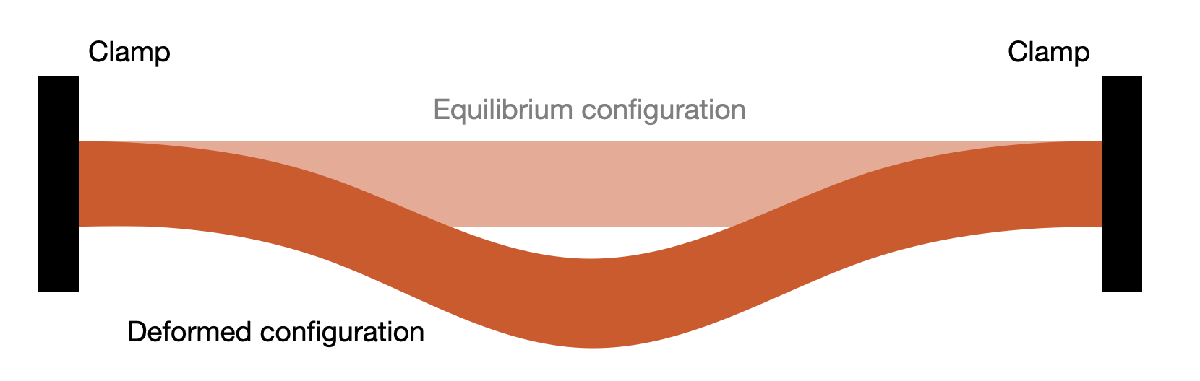

[1] S. Jain, P. Tiso, and G. Haller, Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds, *Journal of Sound and Vibration* 423 (2018) 195-211. [https://doi.org/10.1016/j.jsv.2018.01.049](https://doi.org/10.1016/j.jsv.2018.01.049) 

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

Building FE model


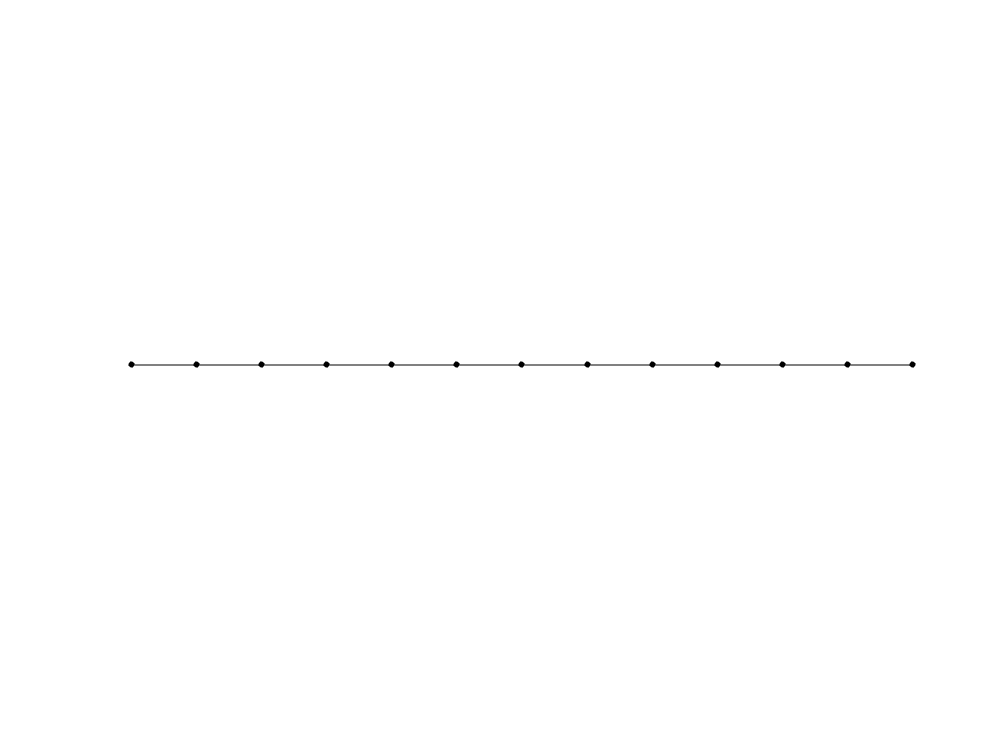

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


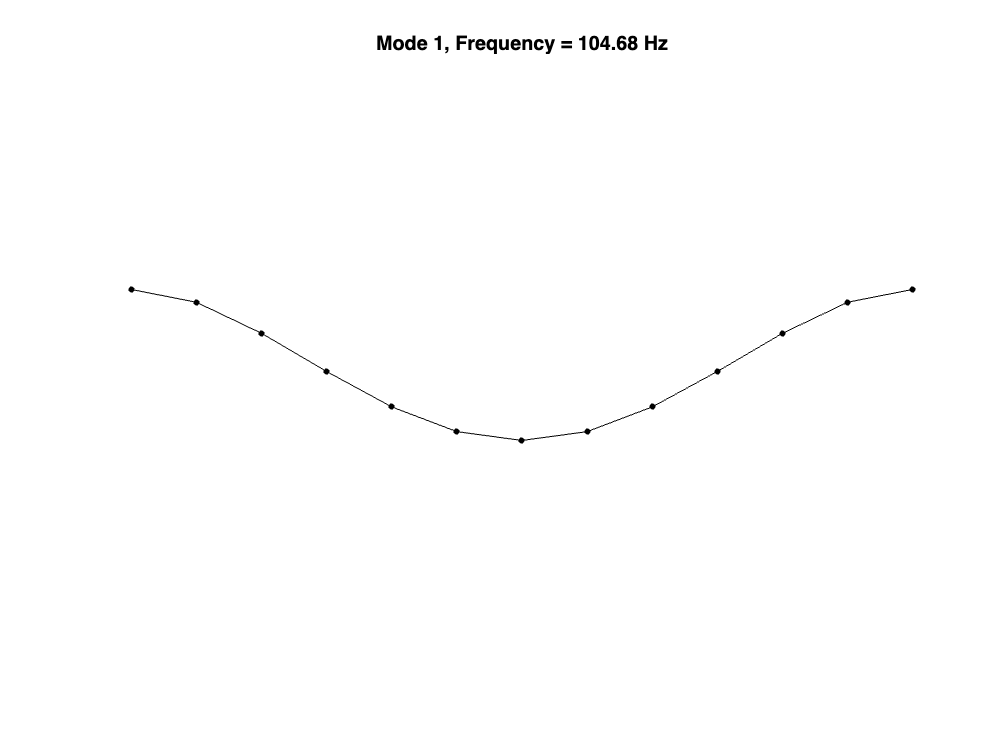

Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


nElements = 12;
[M, C, K, fnl, fExt, outdof, PlotFieldonDefMesh] = buildModel(nElements);

n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation. In this case we will use one trajectory as the training set and another one as the test set.

loads = -[12 14]*1e3;
nTraj = size(loads, 2);
indTest = 1;
indTrain = 2;

We now set the initial conditions for the trajectories. Our test set trajectory is initialized by applying a point load at the midpoint of the beam. The load is removed at the start of the simulation. For the training trajectory, we use a different point load magnitude. We expect the trajectories to eventually converge onto a slow 2D manifold, which will be identified and used to reduce the system dynamics.

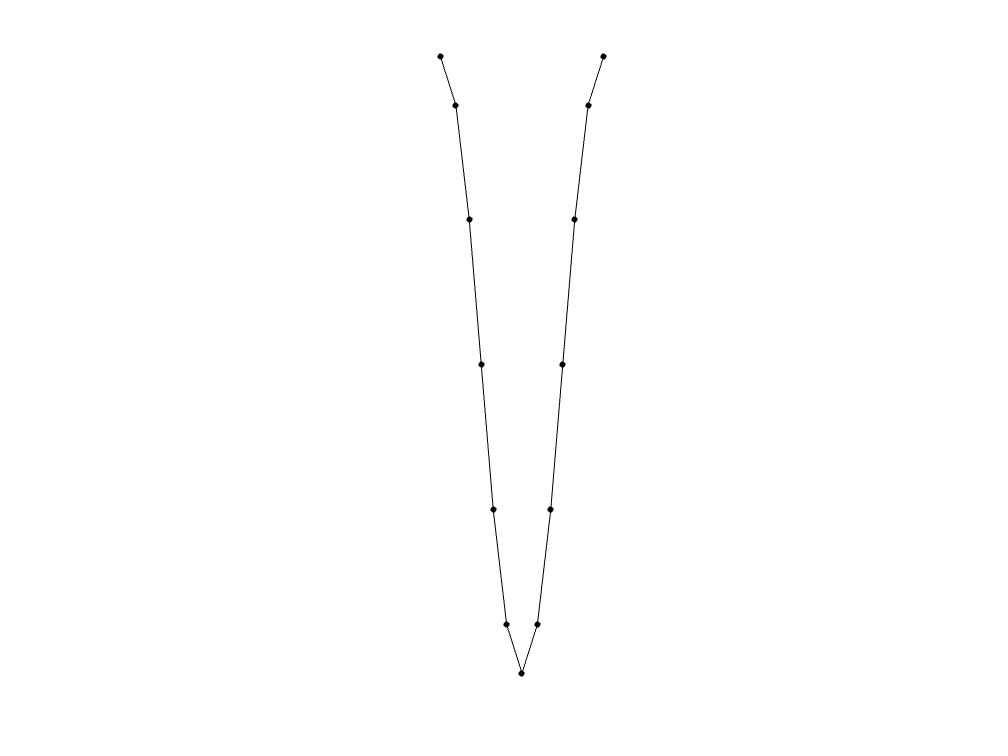

loadvector = loads.*fExt;
IC = getStaticResponse(K, M, F, loadvector, true, PlotFieldonDefMesh);

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the midpoint displacement, so the `observable` function is selected to save only the transverse displacement of the center element. We also make sure that the data is sampled with a sufficiently high frequency.

To save execution time and avoid rerunning the simulation, `newMeasurement` can be set to `false`.

newMeasurement = false;
observable = @(x) x(outdof,:);
slowTimeScale = 2*pi/abs(lambda(1));
numberPeriods = 125; numberPointsPerPeriod = 100;
if newMeasurement
    endTime = numberPeriods*slowTimeScale;
    nSamp = numberPeriods*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    xData = integrateTrajectories(F, endTime, IC, nSamp, observable);
    DataInfo = struct('nElements', nElements, 'loadvector', loadvector);
    save('dataVKDecay.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp')
else
    load dataVKDecay.mat
    if nElements ~= DataInfo.nElements
       error('The loaded data comes from a model with a different number of elements.') 
    end
end

## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

SSMDim = 2;
overEmbed = 0;
yData = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


## Data analysis

We need to make sure that the data that we use to identify the slow manifold lies close to it. We can do this by plotting a spectrogram of the beam tip displacement. In general, there may be many vibratory modes present at first, but the faster ones quickly die out.

showSpectrogram(yData(indTrain,:), 1);
ylim([0,abs(lambda(1))/2/pi*5])

We plot the tip displacement over time for closer inspection. 

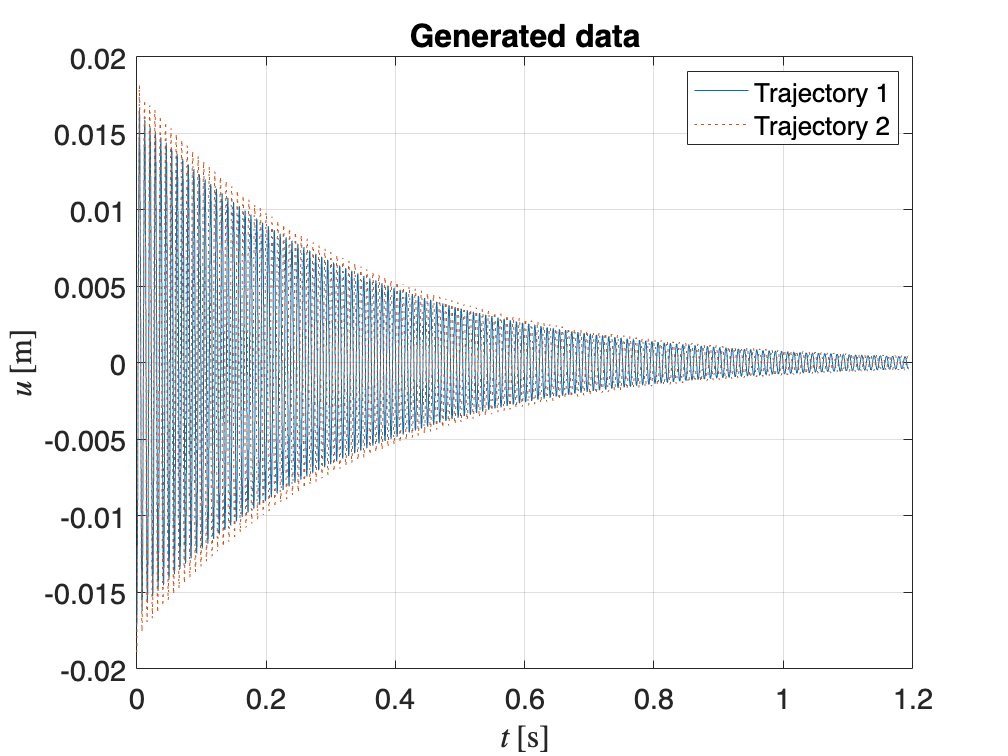

customFigure();
plot(xData{1,1}, xData{1,2}, xData{2,1}, xData{2,2}, ':');
xlabel('$t \, [$s$]$','Interpreter','latex'); 
ylabel('$u \, [$m$]$','Interpreter','latex'); 
legend({'Trajectory 1', 'Trajectory 2'})
title('Generated data')

Next, we use the information from the spectrogram and plot to remove the first part of the training data. After the first few oscillations have passed, there is one dominant mode left in the frequency spectrum. In this case, faster modes die out very quickly, so we can use almost all of the data. We must however remove the first transient to fulfill the assumption that trajectories lie close to the SSM. We keep only the time interval `sliceInt`.

sliceInt = [4*slowTimeScale, endTime];
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

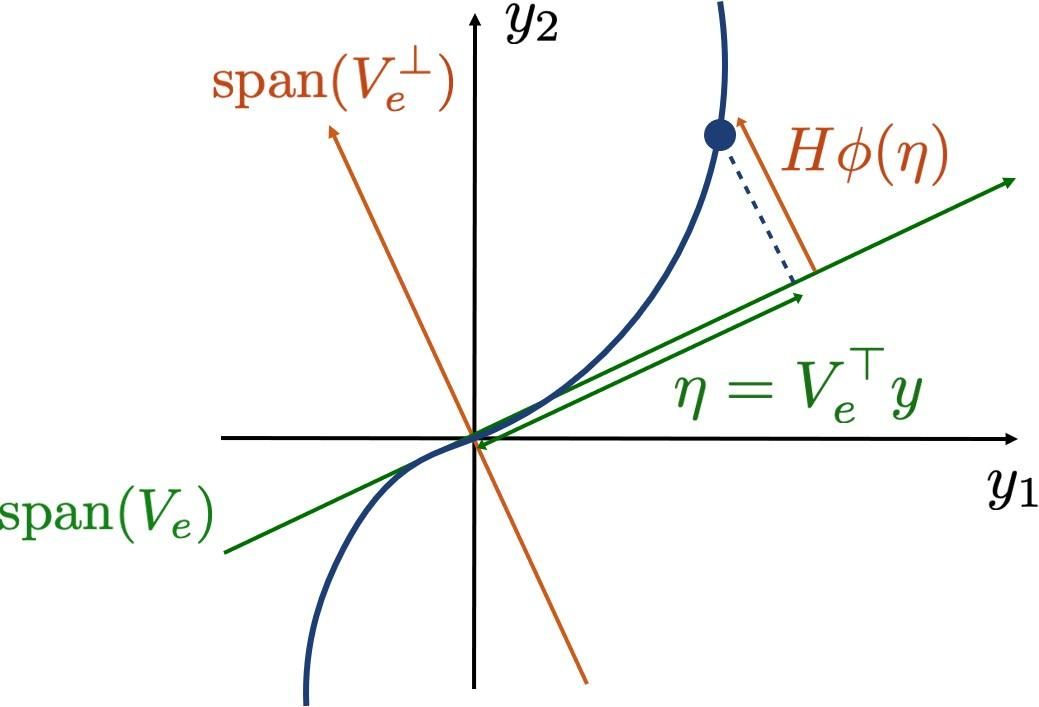

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem is formulated as the minimization of a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMGeometry`.

SSMOrder = 1;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace:

$\eta = V_e^\top y$.

etaData = projectTrajectories(IMInfo, yData);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

We plot the test and training set trajectories projected onto the plane. After all initial transients die out, the trajectories seem to be confined to a slowly decaying oscillating eigenmode. This is the data we will use to train our reduced order model for the dynamics. In these coordinates, the initial transient that we removed is visible as irregular high-frequency oscillations in the first revolution.

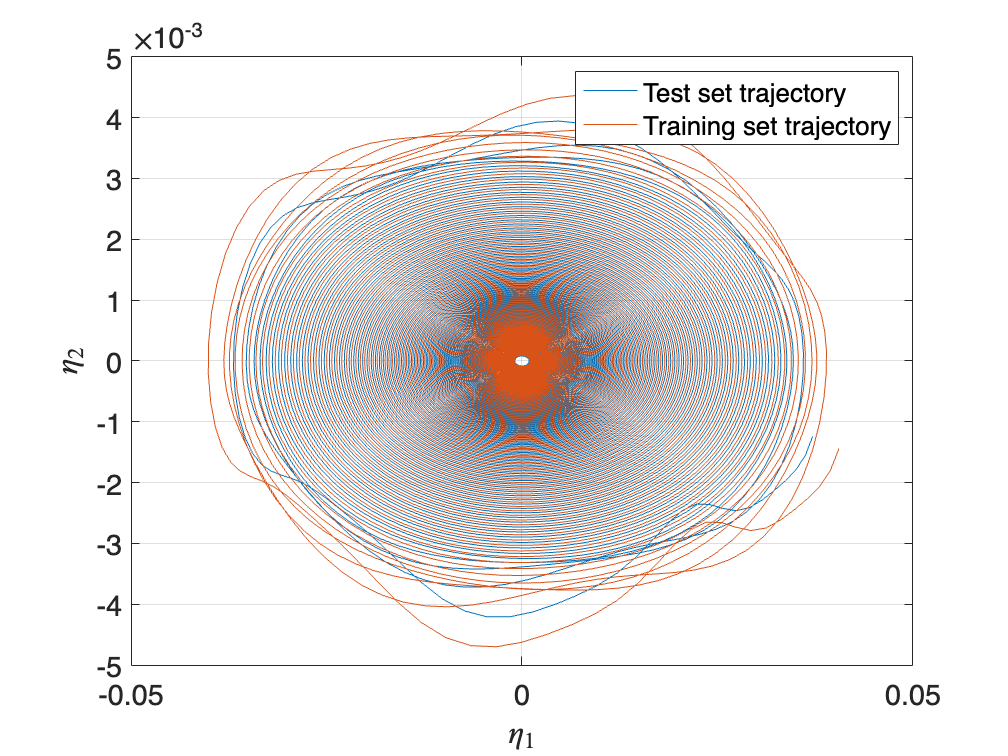

plotReducedCoordinates(etaData);
legend({'Test set trajectory', 'Training set trajectory'})

Furthermore, we draw the end tip component of the manifold shape along with the truncated trajectory from the training set. 

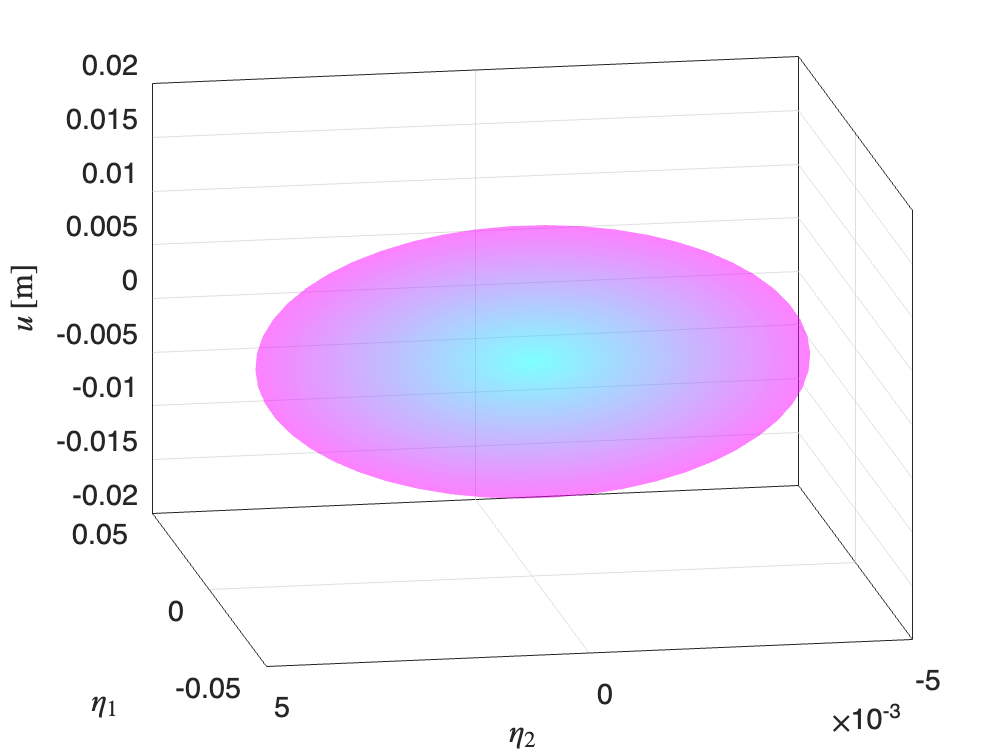

plotSSMWithTrajectories(IMInfo, 1, yDataTrunc(indTrain,:))
view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) =Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          879.584                      2.03e+03
     1           2          269.471    0.000491843       3.46e+03  
     2           4          102.793       0.277922            611  
     3           5          17.7056              1            255  
     4           6          6.88123              1           40.9  
     5           7          6.41221              1           53.8  
     6           9          6.14447       0.409598           49.8  
     7          10          5.58621              1           18.6  
     8          11          5.34047              1           19.3  
     9          12          5.10719              1           21.2  
    10          13          4.82521              1           15.1  
    11          14

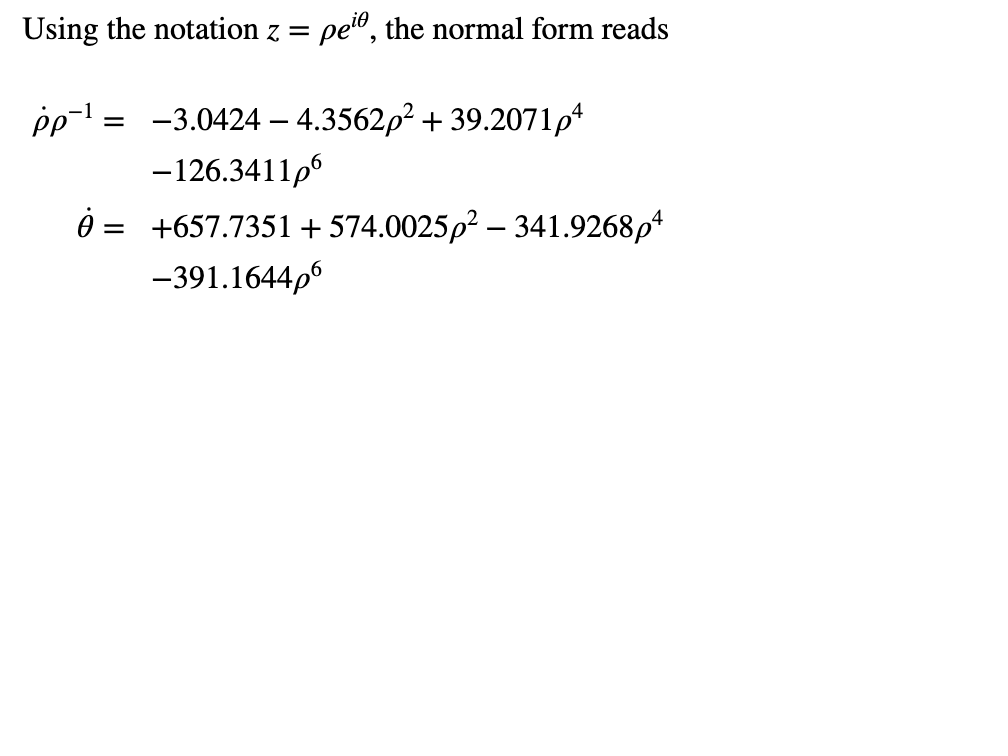

ROMOrder = 7;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);

## Evaluation of reduced dynamics

The normalized mean trajectory error NMTE is computed as the average distance of the predicted trajectory to the measured one in the observable space, normalized by the observable vector with maximum norm in the data. 

normedTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
NMTE = mean(normedTrajDist(indTest))

NMTE = 0.0255

We plot the true test set trajectory in the reduced coordinates and compare it to the prediction. 

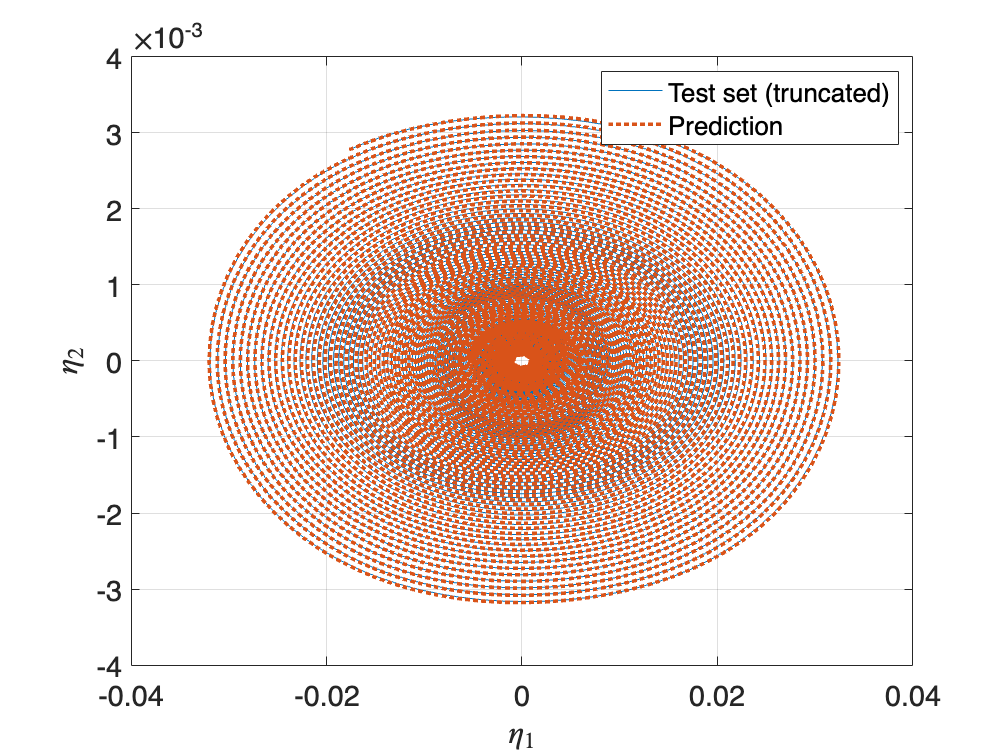

plotReducedCoordinates(etaDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set (truncated)', 'Prediction'})

We also plot the measured and predicted tip displacement. The reduced model seems to do well on previously unseen data, provided that it is close to the 2D manifold.

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', 'DisplayName', {'Test set', 'Prediction'})
ylabel('$u \, [$m$]$','Interpreter','latex')

We compare the estimated eigenvalues of the continuous evolution function to the ones computed from the linearized system. 

lambda = sort(lambda);
DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues = 1.0e+02 *

  -0.0309 - 6.5772i
  -0.0309 + 6.5772i


reconstructedEigenvalues = sort(RDInfo.eigenvaluesLinPartFlow)

reconstructedEigenvalues = 1.0e+02 *

  -0.0304 - 6.5774i
  -0.0304 + 6.5774i


## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency. In this delay-embedding example, the reference physical amplitude is that of the first coordinate.

zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
rhoCal = abs(zData{indTest(1),2}(1,1));
amplitudeFunction = @(x) x(1,:);
figure
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoCal);
subplot(121); ylabel('$u \, [$m$]$','Interpreter','latex')
subplot(122); ylabel('$u \, [$m$]$','Interpreter','latex')

## Forced response curves

The data-driven model trained on autonomous data can now be used for forced response predictions. With the addition of forcing, the normal form dynamics becomes 

$$\dot{z} =N(z) + f_{red} e^{i\Omega t}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude. For FRC extraction, we analytically compute fixed points of the polar normal form via a closed form solution. Our results are compared to those of SSMTool and of direct numerical integrations.

### SSMTool

We first compute the forced response using the full model with SSMTool. We will later compare this result with that obtained from our data-driven reduced order model. 

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 4.698027e-03
modal damping ratio for 2 mode is 1.295171e-02
modal damping ratio for 3 mode is 2.539951e-02
modal damping ratio for 4 mode is 4.202081e-02
modal damping ratio for 5 mode is 6.286832e-02

 The first 10 nonzero eigenvalues are given as 
   1.0e+03 *

  -0.0031 + 0.6577i
  -0.0031 - 0.6577i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0.0903 + 3.5548i
  -0.0903 - 3.5548i
  -0.2472 + 5.8777i
  -0.2472 - 5.8777i
  -0.5533 + 8.7842i
  -0.5533 - 8.7842i

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6 

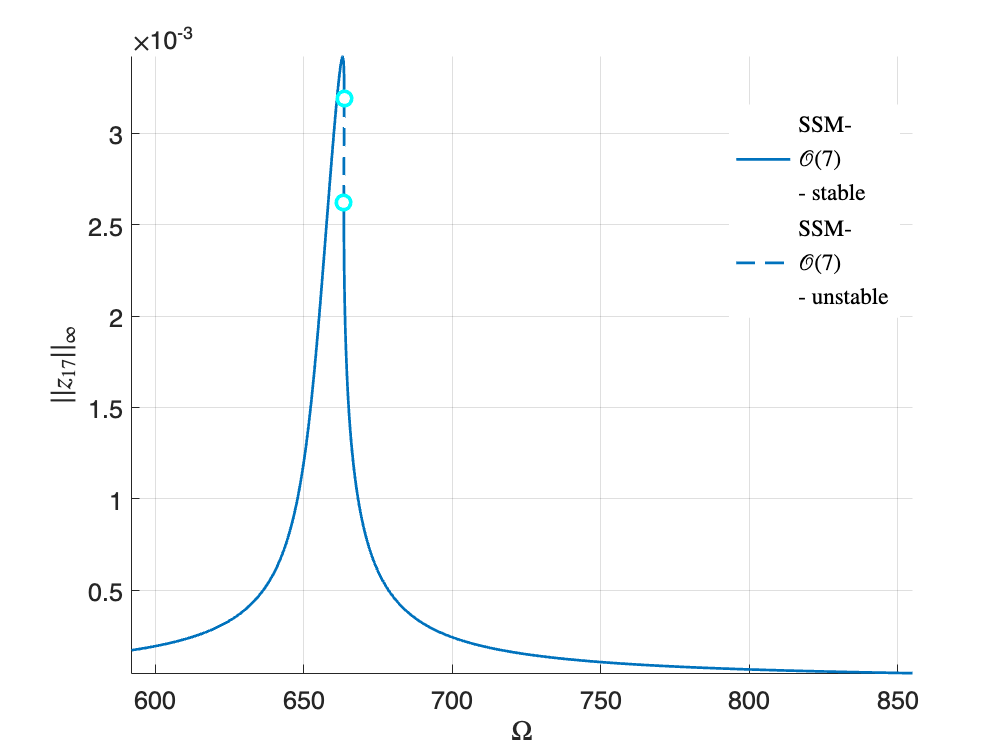

Total time spent on FRC computation upto O(7) = 00:00:09
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

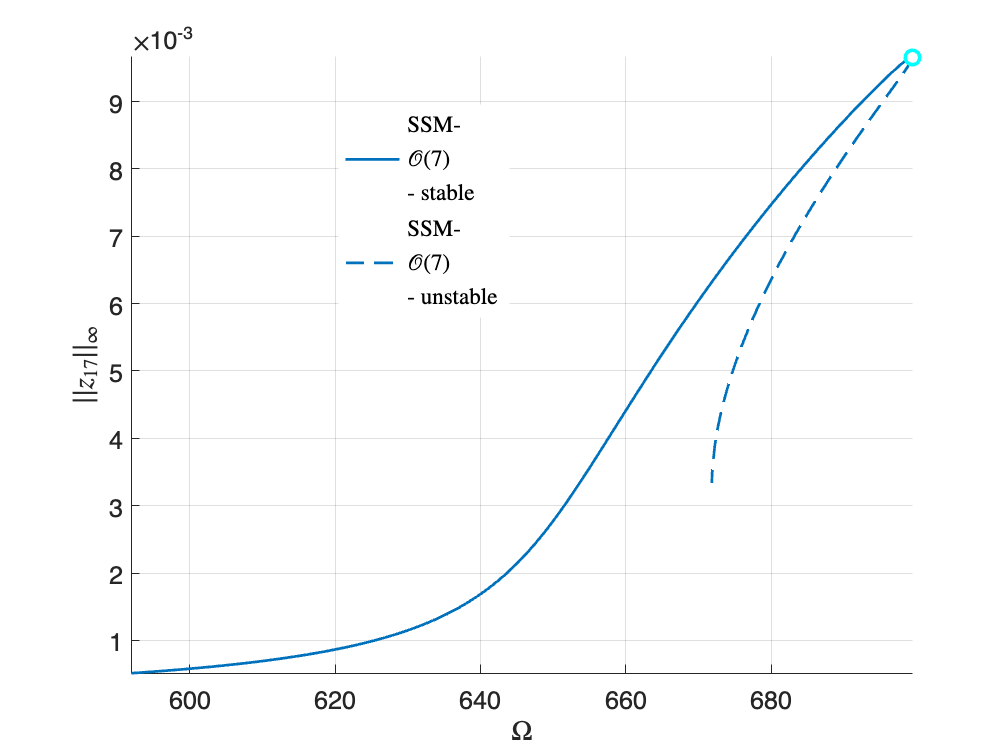

Total time spent on FRC computation upto O(7) = 00:00:05
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

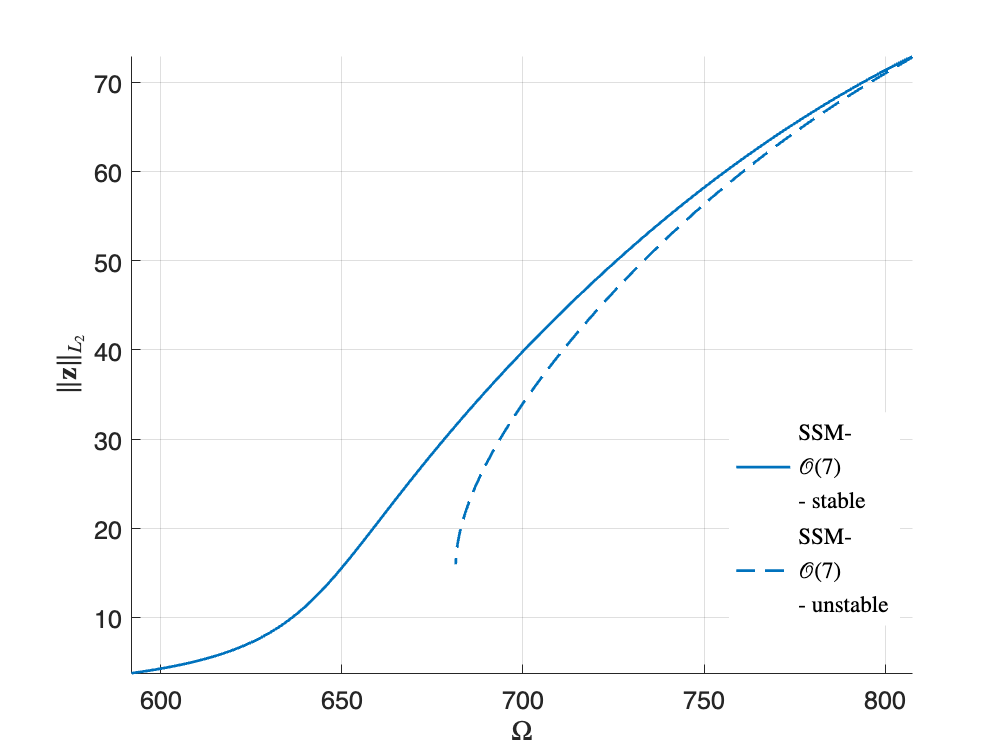

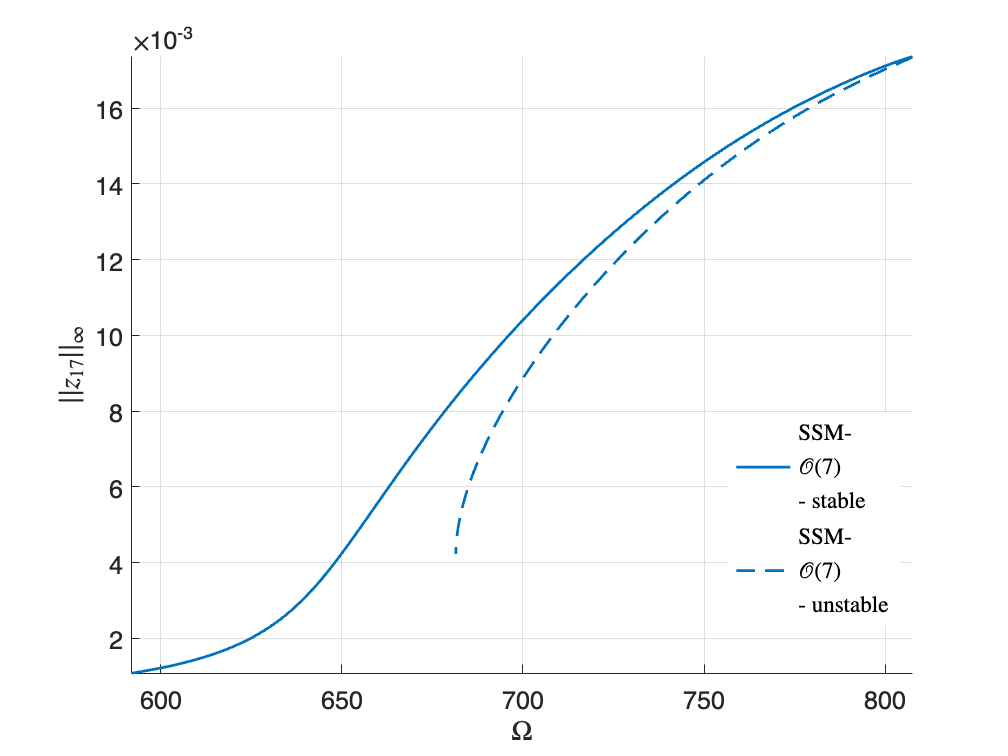

Total time spent on FRC computation upto O(7) = 00:00:12
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

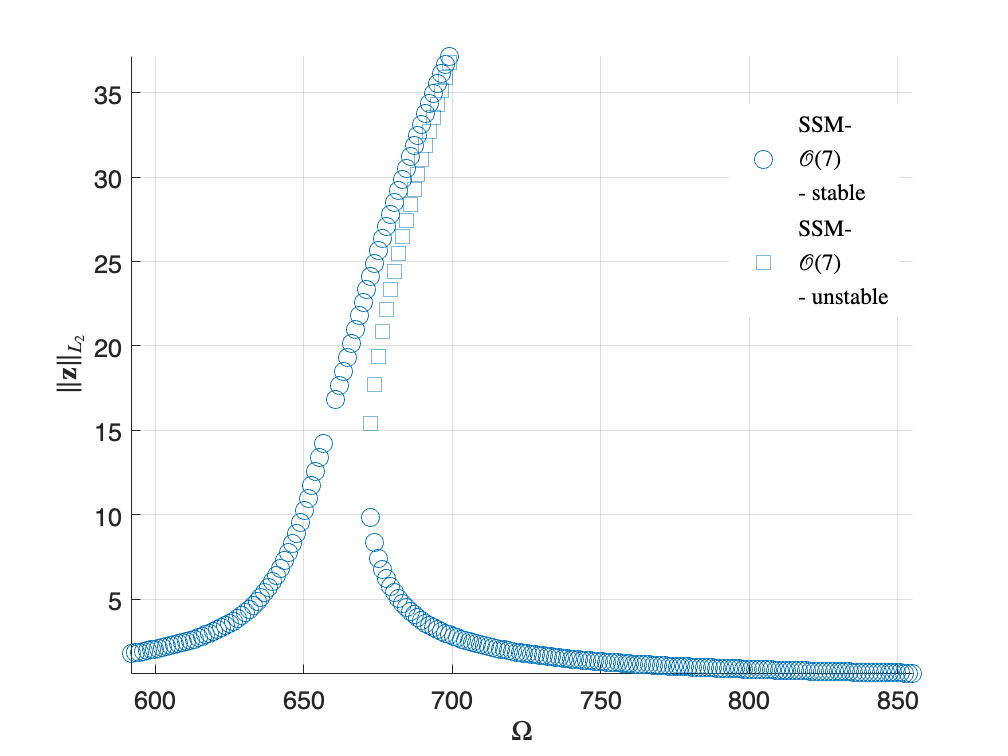

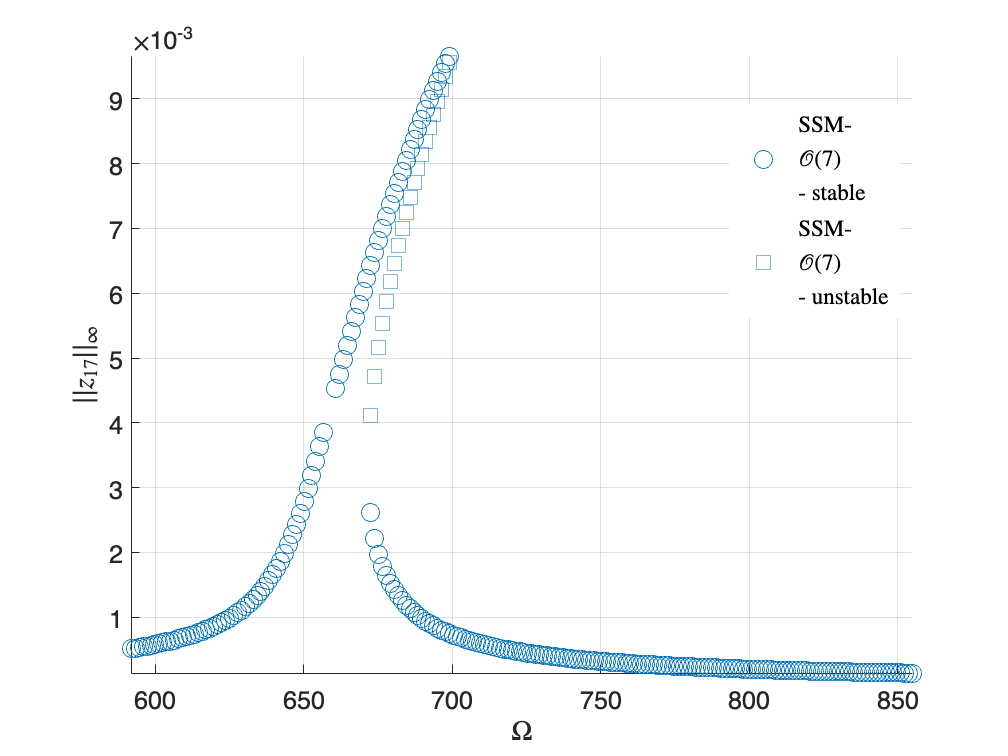

Total time spent on FRC computation upto O(7) = 00:00:03
*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     5     0
     6     0
     6     1
     7     1
     7     2
     8     2
     0     5
     0     6
     1     6
     1     7
     2     7
     2     8
     8     0
     9     0
     9     1
     0     8
     0     9
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+03 *

  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 + 1.8131i
  -0.0235 - 1.8131i
  -0

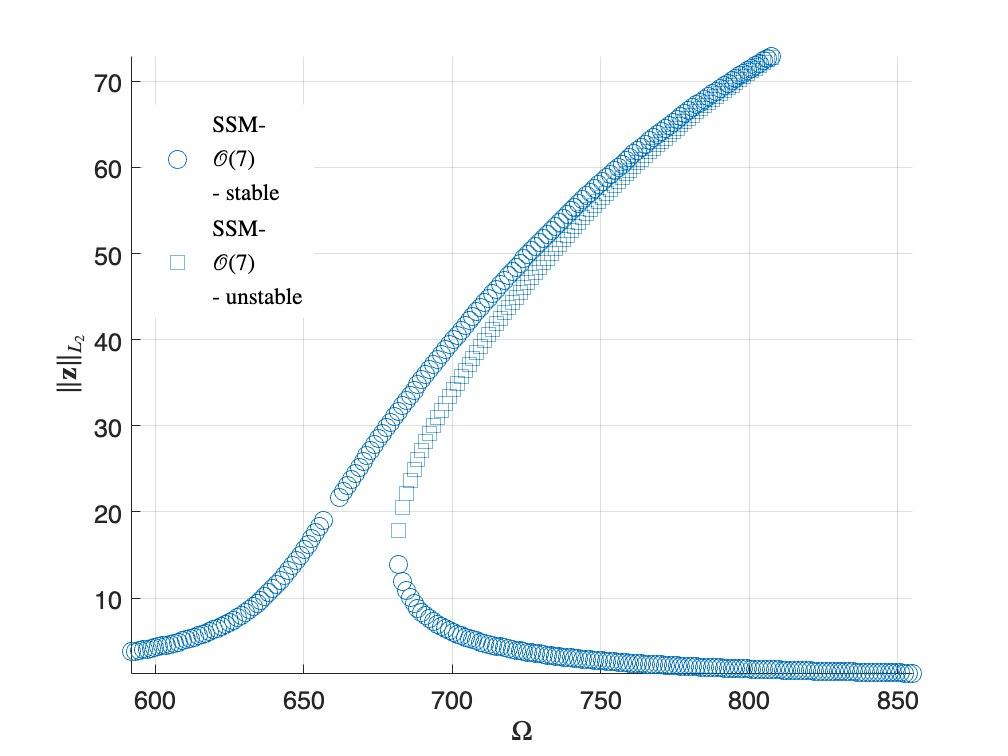

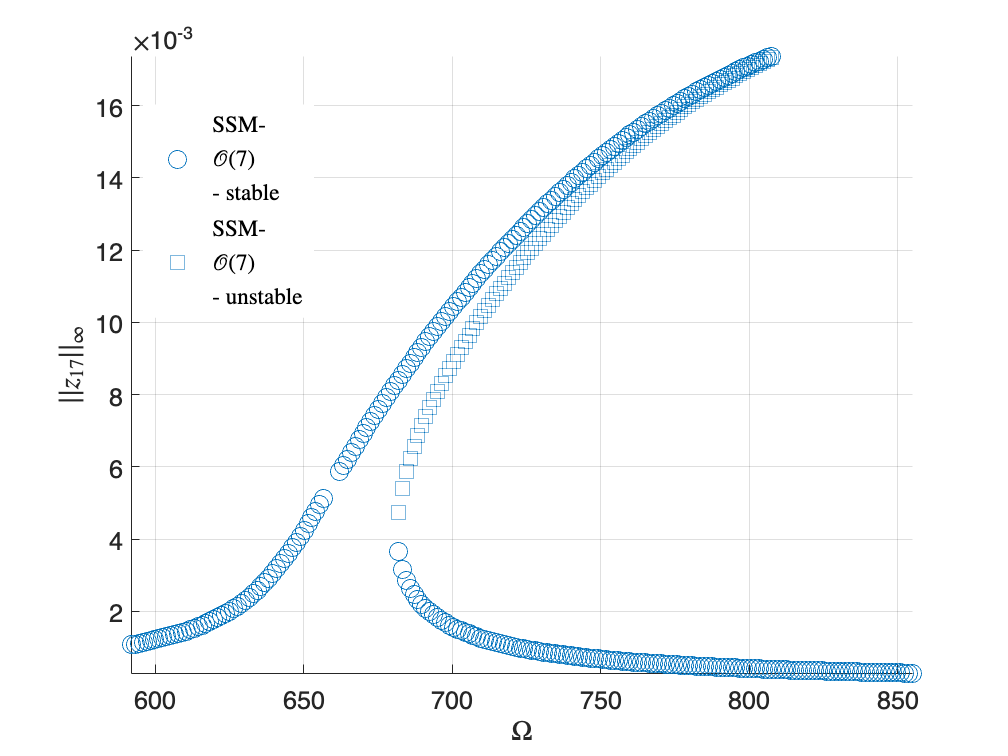

Total time spent on FRC computation upto O(7) = 00:00:03


fFull = [15 45 95]; % forcing levels in the full state space
omegaSpan = abs(imag(lambda(1)))*[0.9 1.3];
FRCSSMTool = SSMToolFRCcustom(M, C, K, fnl, fExt, fFull, outdof, omegaSpan, ROMOrder,2e3); % to pick up some hard continuation points

### Numerical integration

For the purpose of validation and calibration, we also perform a frequency sweep of the system. To save computational time and avoid reruns, `newSweep` can be set to `false`.

newSweep = false;
if newSweep
    fSweep = fFull(end)*(M\fExt);
    FRCSweep = integrateSweep(F, [650,800], n, fSweep, observable, ...
        'initRevolutions',150,'stepRevolutions', 150, 'step', 5);
    DataInfo = struct('nElements', nElements, 'fSweep', fSweep, ...
        'outdof', outdof);
    save('dataVKSweep.mat', 'DataInfo', 'FRCSweep')
else
    load('dataVKSweep.mat', 'DataInfo', 'FRCSweep')
end

#### FRC calibration

We use our normal form dynamics to extract a forced response curve. To this end, we need to define the forcing amplitude in the normal form. We do this by passing to `calibrateFRC` a frequency and a point $y_\mathrm{cal}$ in the observable space. At the defined frequency, the calibrated FRC will reach the amplitude of this point. 

The vector $y_\mathrm{cal}$ lies in a delay embedded space, and can be computed either from a delay embedded time-varying response signal, or from a scalar maximal response that is artifically delay embedded. Here, `integrationBasedCalibration` allows for simulation of the forced system, where $y_\mathrm{cal}$ is computed from the stable response signal. Alternatively, a scalar value $u_\mathrm{cal}$ can be mapped to the observable space via a cosine function oscillating at the forcing frequency.

integrationBasedCalibration = false;
embedDim = size(yData{1,2}, 1);

if integrationBasedCalibration
    Omega = abs(imag(lambda(1)))*0.96;
    uICLinGuess = full(fFull*((-Omega^2*M+K)\fExt));
    FForced = @(t,x,w) F(t,x) + [zeros(n,1); fFull(end)*(M\fExt)*cos(w*t)];
    opts = odeset('RelTol', 1e-4); 
    [t_sim,x_sim] = ode15s(@(t,x) FForced(t,x,Omega),[0 20*2*pi/Omega], [uICLinGuess; zeros(n,1)],opts);
    customFigure(); plot(t_sim,x_sim(:,outdof),'Linewidth',1); drawnow;
    [t_sim,x_sim] = ode15s(@(t,x) FForced(t,x,Omega),t_sim(end)+[0 1*2*pi/Omega], x_sim(end,:)',opts);
    plot(t_sim,x_sim(:,outdof),'Linewidth',1); drawnow;
    uCal = max(abs(x_sim(:,outdof)));
    yCal(:,1) = uCal*cos(Omega*dt*((1:embedDim)-ceil(0.5*embedDim))).';
else
    yCal = zeros(embedDim,length(fFull)); Omega =650*ones(1,length(fFull));
    for iFRC = 1:length(fFull)
    % calibrate at FRC point
    FRC_i = FRCSSMTool.(['F' num2str(iFRC)]);
    [~,pos] =  min(abs(FRC_i.Freq-Omega(iFRC)));
    Omega(iFRC) = FRC_i.Freq(pos); 
    uCal = FRC_i.Amp(pos); 
    yCal(:,iFRC) = uCal*cos(Omega(iFRC)*dt*((1:embedDim)-ceil(0.5*embedDim))).';
    end
end

% forcing levels in the normal form space
fRed = calibrateFRC(IMInfo, RDInfo, yCal, Omega)

fRed =     0.2968
    0.8888
    1.8869


#### Data-driven FRC computation

We now compute the FRC directly from the reduced dynamics model.

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


FRCData = analyticalFRC(IMInfoF, RDInfoF, fRed, amplitudeFunction);

### FRC plot and evaluation

Comparison of the FRCs from SSMTool and SSMLearn with numerical integration shows that SSMLearn outperforms SSMTool at this forcing level. 

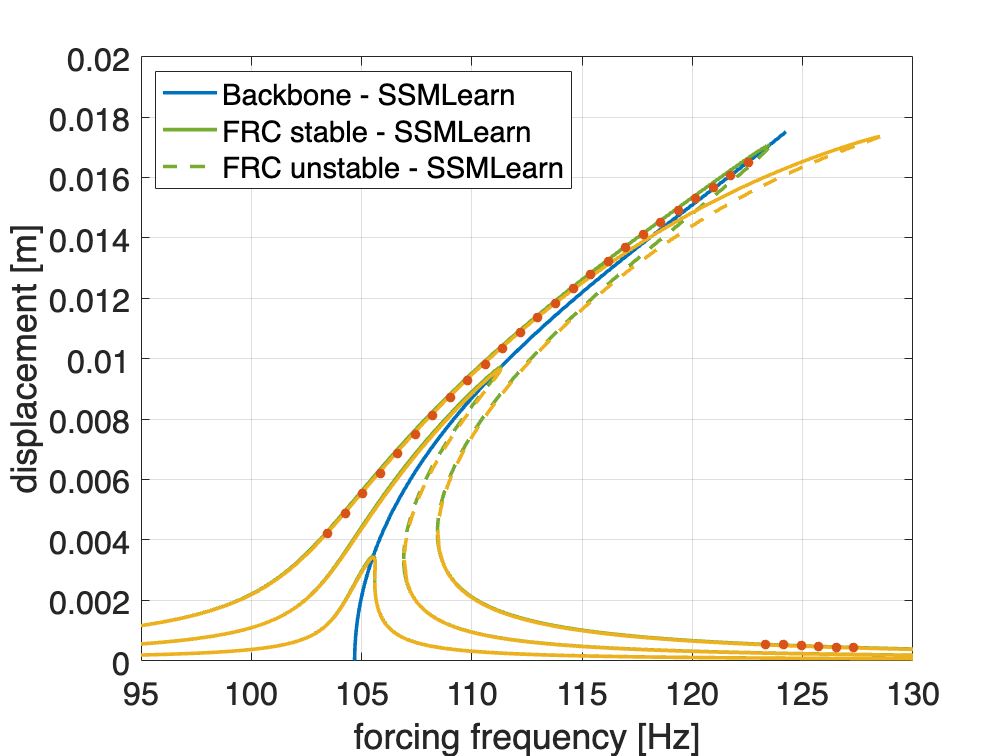

customFigure();
colors = colororder;
plot(BBCInfo.frequency/2/pi, BBCInfo.amplitude,'Color',colors(1,:),'Linewidth',2,'DisplayName', 'Backbone - SSMLearn')
plotFRC(FRCData, colors(5,:), '- SSMLearn','freqscale',2*pi)
plotFRC(FRCSSMTool, colors(3,:), '- SSMTool','freqscale',2*pi)
plot(FRCSweep.omega/2/pi,FRCSweep.amp,'.','MarkerSize',16,'Color',colors(2,:),'DisplayName','Numerical integration');
xlim(omegaSpan)
ylim([0,1.06*max(FRCSSMTool.(['F' num2str(length(fFull))]).Amp)])
xlabel('forcing frequency [Hz]')
ylabel('displacement [m]')
set(gca, 'FontSize', 18)
xlim([600 800]/2/pi)
xlim([95 130])
ylim([0 0.02])
legend('location','NW')

### Evaluation of the conjugacy error

We now perform crossvalidation on the normal form reduced dynamics. Specifically, we vary the polynomial order and track the training and testing performances on the conjugacy error which is used to learn the normal form.

Evaluating ROM at order : 3 ... Done. 
Evaluating ROM at order : 5 ... Done. 
Evaluating ROM at order : 7 ... Done. 
Evaluating ROM at order : 9 ... Done. 
Evaluating ROM at order : 11 ... Done. 
Evaluating ROM at order : 13 ... Done. 


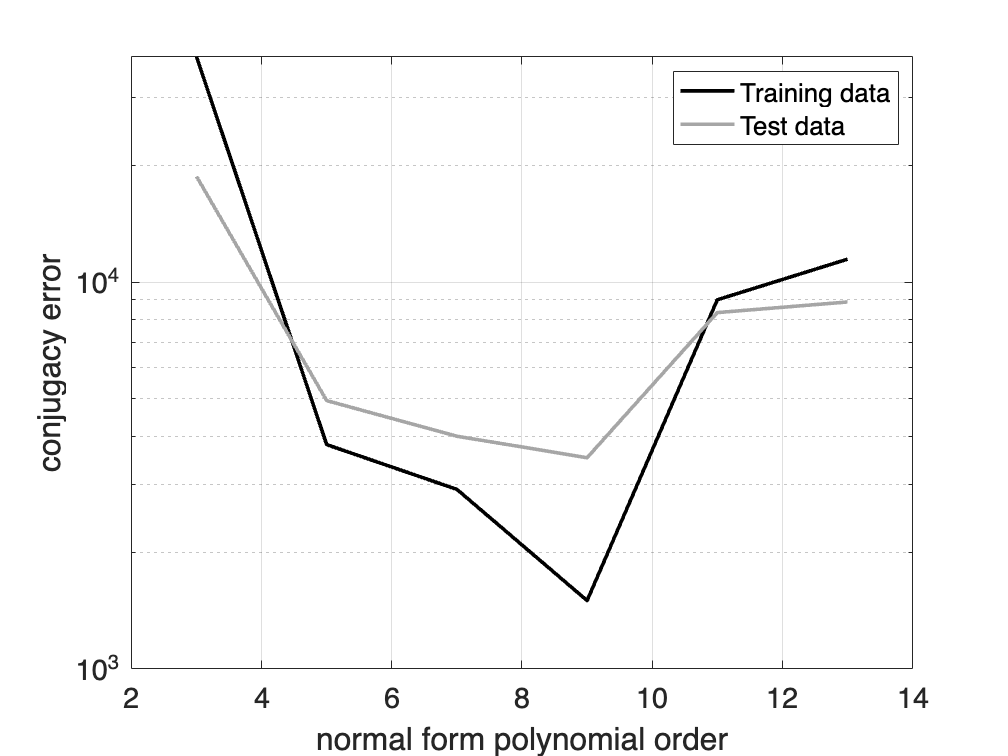

errorInfo = conjugacyErrorTrend(etaDataTrunc,indTrain,indTest,3:2:13);